# Proyecto SCV

Definición y objetivos del proyecto

Forma de trabajar: se han separado todas las funciones que intervienen en las distintas pruebas y se han guardado en diferentes .m por el momento. Desde este livescript solo se ejecutan las distintas pruebas de la competición y se le dan los parámetros. 

### `Parámetros del vehículo`

p = struct(); 

p.m    = 230;      % masa [kg]                              
p.g    = 9.81;     % gravedad [m/s^2]
p.rho  = 1.225;    % densidad del aire [kg/m^3]
p.Cd   = 1.0;      % coef. aerodinámico                       
p.Af   = 1.1;      % área frontal [m^2]                        
p.fr  = 0.022;    % coef. de resistencia a la rodadura       
p.Fx_drive_max = 2500;   % fuerza motriz máxima [N]           
p.Fx_brake_max = 5000;   % fuerza de frenado máxima [N]       
p.theta        = 0;      % inclinación de la calzada [rad]

% adherencia por eje
p.mu_t = 1.5; %Pongo 0.8 estaba 1.5 
p.mu_d = 0.95*p.mu_t; 

% dinámica lateral del vehículo
p.ld = 0.765; % CG-eje delantero [m] 
p.lt = 0.765; % CG-eje trasero [m]
p.Iz = 130; % inercia en guiñada [kg·m^2]
p.Cad = 35000; % rigidez de deriva delantera [N/rad]
p.Cat = 50000; % rigidez de deriva trasera [N/rad]

% Ley ACC 

p.d0 = 6; % distancia mínima de parada [m]
p.h = 1.5; % umbral de tiempo ("headway") [s]
p.Kv = 1.5; % ganancia modo velocidad
p.Kg = 0.4; % Ganancia modo distancia 
p.Kd = 1.0; % Ganancia derivativa sobre velocidad relativa 
p.jerk_max = 2.5; % tasa de variación de la aceleración (sobreaceleración; min sacudidas max confort) [m/s^3]

% propios de la simulación (esto es para no tener que ejecutar una cosa y
% otra primero para que funcione) 
p.v_set = 15; % velocidad de crucero deseada [m/s] (90 km/h) 
p.dt = 0.002; % paso de la simulación 
esc.lead_X0 = 30; % posición inicial del lider [m]
esc.Tmax = 30; % tiempo máx simulación

## `E1 · Aceleración y frenada  (ctrl, z0, simulación, resultados)`

### Geometría del circuito de pruebas

Vamos a simular una aceleración máxima durante 75 m seguida de una frenada en caja que deberá completarse en menos de 25 m (límite máximo de frenada a los 100 m). 

p.x_meta = 75;     % línea de cronometraje [m]
p.x_box  = 100;    % final de la caja de frenada [m]
% [CAMBIO] datos del controlador y estado inicial de E1
ctrl = struct();
ctrl.v_cru  = 25;  % velocidad de crucero objetivo [m/s]
ctrl.x_fren = 78;  % distancia a la que se ordena frenar [m]
ctrl.Kp = 800;
ctrl.Ki = 200;
z0 = [0; 0; 0; 0; 0; 0];  % [CAMBIO] 6 estados (pasoDinamico)


#### Simulación

dt   = 0.005;
Tmax = 20; 

[hist, t_evento] = simularE1(z0, p, ctrl, dt, Tmax);



### Resultados 

**Qué esperar**: Deberíamos observar como el monoplaza acelera desde parado hasta la velocidad de crucero establecida (90 km/h) y la mantiene hasa cruzar la linea de 75m donde hemos establecido el comienzo de la frenada. Tras cruzar esta línea frena y se detiene dentro de la caja (antes de 100 m aprox).

fprintf('E1 — cruza %.0f m en  t = %.2f s\n', p.x_meta, t_evento);

E1 — cruza 75 m en  t = 4.25 s


fprintf('     se detiene en  X = %.1f m  (t = %.2f s)\n', hist.x(end), hist.t(end));

     se detiene en  X = 98.4 m  (t = 6.58 s)


fprintf('     v_max = %.1f m/s = %.0f km/h\n', max(hist.vx), max(hist.vx)*3.6);

     v_max = 24.8 m/s = 89 km/h


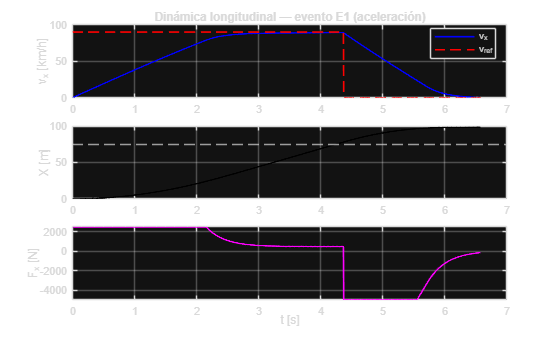

figure('Name','L1 · E1 — resultados','Color','w');
subplot(3,1,1);
  plot(hist.t, hist.vx*3.6,'b', hist.t, hist.vr*3.6,'r--','LineWidth',1.2);
  ylabel('v_x [km/h]'); grid on; legend('v_x','v_{ref}','Location','best');
  title('Dinámica longitudinal — evento E1 (aceleración)');
subplot(3,1,2);
  plot(hist.t, hist.x,'k','LineWidth',1.2); yline(p.x_meta,'--');
  ylabel('X [m]'); grid on;
subplot(3,1,3);
  plot(hist.t, hist.Fx,'m','LineWidth',1.2);
  ylabel('F_x [N]'); xlabel('t [s]'); grid on;


  animarE1(hist, p, ctrl)   % tras simularE1 

## `E2 · Skidpad                (geom, ctrl, simulación, resultados)`

### Simulación

ctrl = struct();
ctrl.v_skid = 5; %[m/s] 18 km/h
ctrl.Kp = 800;
ctrl.Ki = 200;
  
  
%% SIMULADOR DE LA PRUEBA DEL SKIDPAD [NO MODIFICAR]
geom = struct();
geom.R_in = 15.25/2; % radio interior (conos azules) [m]
geom.R_out = geom.R_in + 3; % radio exterior (conos amarillos; carril de 3m) [m]
geom.R = (geom.R_in + geom.R_out)/2; % radio de la línea central [m]
z0 = [0; -geom.R; 0; ctrl.v_skid; 0; 0];

dt   = 0.002; 
Tmax = 2.5*2*pi*geom.R/ctrl.v_skid; % ~2.5 vueltas (la 2ª es la cronometrada)

histCin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoCinematico);
histDin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoDinamico);

idx = round(2*numel(histCin.t)/3):numel(histCin.t);
Rcin = mean(histCin.vx(idx)./max(histCin.r(idx),1e-6));
Rdin = mean(histDin.vx(idx)./max(histDin.r(idx),1e-6)); 

%animarE2(histDin, geom, p, 20, false, '', histCin)

### Resultados 

Deberíamos observar como el monoplaza que sigue el modelo cinemático traza un cículo de radio ~9m (geometría pura) mientras que el modelo dinámico traza un radio ligeramente mayor debido al subviraje (ligero subviraje debido a angulos de deriva pequeños; determinados por la rigidez de deriva de ambos ejes). 

fprintf('Ackermann R = %.2f m  (delta = %.2f deg)\n', geom.R, atan((p.ld+p.lt)/geom.R)*180/pi);

Ackermann R = 9.12 m  (delta = 9.52 deg)


fprintf('Radio medido — cinemático: %.2f m | dinámico: %.2f m\n', Rcin, Rdin);

Radio medido — cinemático: 9.13 m | dinámico: 9.36 m


fprintf('Subviraje: el dinámico traza %.1f%% más radio.\n', 100*(Rdin-Rcin)/Rcin);

Subviraje: el dinámico traza 2.6% más radio.


fprintf('Tiempos (regla FS: se cronometra la 2ª vuelta de cada círculo):\n');

Tiempos (regla FS: se cronometra la 2ª vuelta de cada círculo):


informarVueltas('cinemático', histCin);

   cinemático: 2ª vuelta = 11.47 s


informarVueltas('dinámico  ', histDin);

   dinámico  : 2ª vuelta = 11.76 s


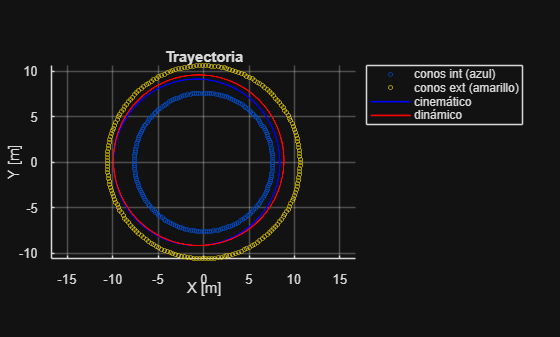

%figure('Name','L2 · Skidpad','Color','w');

%subplot(2,2,1);  
figure; hold on; axis equal; grid on; 
  th = linspace(0,2*pi,200);
  plot(geom.R_in*cos(th), geom.R_in*sin(th), 'o','Color',[0 .3 .8],'MarkerSize',3);
  plot(geom.R_out*cos(th),geom.R_out*sin(th),'o','Color',[.9 .8 0],'MarkerSize',3);
  plot(histCin.X, histCin.Y, 'b-','LineWidth',1.2);
  plot(histDin.X, histDin.Y, 'r-','LineWidth',1.2);
  legend('conos int (azul)','conos ext (amarillo)','cinemático','dinámico','Location','bestoutside');
  title('Trayectoria'); xlabel('X [m]'); ylabel('Y [m]');

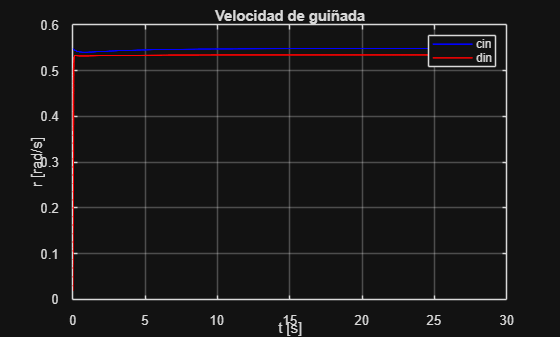


%subplot(2,2,2);
figure
  plot(histCin.t,histCin.r,'b', histDin.t,histDin.r,'r','LineWidth',1.2);
  ylabel('r [rad/s]'); xlabel('t [s]'); grid on; legend('cin','din');
  title('Velocidad de guiñada');

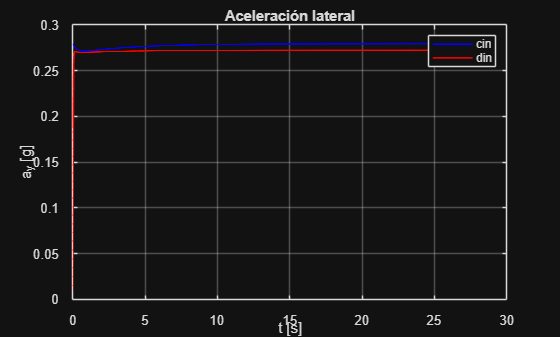


%subplot(2,2,3);
figure
  plot(histCin.t, histCin.vx.*histCin.r/9.81,'b', ...
       histDin.t, histDin.vx.*histDin.r/9.81,'r','LineWidth',1.2);
  ylabel('a_y [g]'); xlabel('t [s]'); grid on; legend('cin','din');
  title('Aceleración lateral');

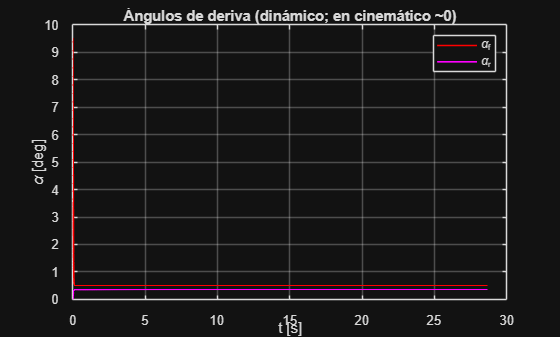


%subplot(2,2,4);
figure
  plot(histDin.t, histDin.af*180/pi,'r', histDin.t, histDin.ar*180/pi,'m','LineWidth',1.2);
  ylabel('\alpha [deg]'); xlabel('t [s]'); grid on; legend('\alpha_f','\alpha_r');
  title('Ángulos de deriva (dinámico; en cinemático ~0)');

## `E4 · ACC                    (esc, simulación, resultados)`

dt = p.dt;
z0 = [0; 0; 0; 0; 0; 0]; % estado inicial
% u: variable de control [Fx; delta]
% z: vector de estado del vehículo [X; Y; psi; vx; vy; r]
% X, Y = posicion del CG global
% psi = rumbo, ángulo de guiñada
% vx, vy = velocidades en eje del chasis
% r = velocidad de guiñada

hist = simularE4(z0, p, esc, dt); 


%animarE4(hist, p)         % tras simularE4

#### Resultados

% Cálculo de las métricas de seguridad
gap_min = min(hist.gap);

fprintf('ACC — separación mínima: %.1f m  (líder frena en t=14 s)\n', gap_min);

ACC — separación mínima: 18.5 m  (líder frena en t=14 s)


if gap_min <= 0
    fprintf('  ¡COLISIÓN! (la ley ACC no mantiene la distancia)\n');
else
    fprintf('  sin colisión: separación siempre > 0\n');
end

  sin colisión: separación siempre > 0


fprintf('  velocidad final ego: %.1f km/h | líder: %.1f km/h\n', ...
        hist.vx(end)*3.6, hist.vl(end)*3.6);

  velocidad final ego: 29.4 km/h | líder: 28.8 km/h


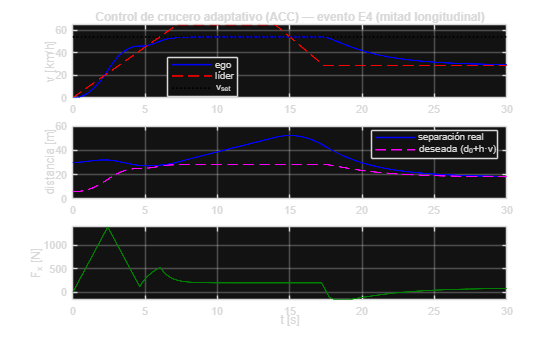

% gráficas
figure('Name','L3 · ACC','Color','w');
subplot(3,1,1);
  plot(hist.t, hist.vx*3.6,'b', hist.t, hist.vl*3.6,'r--', hist.t, p.v_set*3.6*ones(size(hist.t)),'k:','LineWidth',1.2);
  ylabel('v [km/h]'); grid on; legend('ego','líder','v_{set}','Location','best');
  title('Control de crucero adaptativo (ACC) — evento E4 (mitad longitudinal)');
subplot(3,1,2);
  plot(hist.t, hist.gap,'b', hist.t, hist.d_des,'m--','LineWidth',1.2);
  ylabel('distancia [m]'); grid on; legend('separación real','deseada (d_0+h·v)','Location','best');
subplot(3,1,3);
  plot(hist.t, hist.Fx,'Color',[0 .5 0],'LineWidth',1.2);
  ylabel('F_x [N]'); xlabel('t [s]'); grid on;